# `智能控制 课程考查`

# `Indirect Model Reference Aapative RBF Control —— `

# `Initial Parameters Optimized by Generic Algthorim `

(广东工业大学 自动化学院 控制科学与工程 学一 黄国盛 2112004086  2020.11.19）

%GA(Generic Algorithm) to Optimize Initial Parameters of RBF Approaching 
clear all; 
clc;
close all; 
 
G = 3; 
Size = 150; 
CodeL=10; 
pc=0.60;

neuroN = 6;
Sets = 3*neuroN;

for i= 1:1:neuroN % b
 	MinX(i)=1*ones(1); 
 	MaxX(i)=8*ones(1); 
end
for i= (neuroN+1):1:2*neuroN % c
 	MinX(i)=-7.5*ones(1); 
 	MaxX(i)=7.5*ones(1); 
end
for i= (2*neuroN+1):1:3*neuroN % w
 	MinX(i)=-0.75*ones(1); 
 	MaxX(i)=0.75*ones(1); 
end


E = round(rand(Size,Sets*CodeL));    %Initial Code! 
; 
feature_i=0;

for kg=1:1:G 
    time(kg)=kg; 
     
    for s=1:1:Size 
        m=E(s,:); 
 
        for j=1:1:Sets 
            y(j)=0; 
            mj=m((j-1)*CodeL+1:1:j*CodeL); 
            for i=1:1:CodeL 
                y(j)=y(j)+mj(i)*2^(i-1); 
            end 
            f(s,j)=(MaxX(j)-MinX(j))*y(j)/1023+MinX(j); 
        end 
 
        %****** Step 1 : Evaluate BestJ ****** 
        p=f(s,:); 
             
        %[p,BsJ]=rbf_gaf(p,BsJ);
        [p,feature_i] = GA_Training_Func(p,feature_i); 
         
        All_Features(s) = feature_i;    
    end  % 得到每一个个体的 finess 到 All_Features(s)
;  
% 得到当代最好特性Bestfi ，
             
    fi = All_Features;             % 越小越好
    [Oderfi,Indexfi] = sort(fi);   % 特性从小到大排列
    Bestfi = Oderfi(1);            % 最后一个最好，取出他特性
    BestS = E(Indexfi(1),:);       % 取出它的序列
;
    BestFeature_G(kg) = Bestfi; % 保存当代最好特性到 BestFeature_G(kg,:) 
    BestS_G(kg,:) = BestS;  % 保存当代最好序列到 BestS_G(kg,:) 
    
    kg
    BestS; 
    p
    Bestfi
    ;
    
    
%****** Step 2 : Select and Reproduct Operation****** 
    fi_sum=sum(fi); 
    fi_Size=(Oderfi/fi_sum)*Size; 
    
    fi_S=floor(fi_Size);        %Selecting Bigger fi value 
    
    kk=1; 
    for i=1:1:Size 
      for j=1:1:fi_S(i)        %Select and Reproduce  
       TempE(kk,:)=E(Indexfi(i),:);   
         kk=kk+1;              %kk is used to reproduce 
      end 
    end 
   
%************ Step 3 : Crossover Operation ************ 
    for i=1:2:(Size-1) 
        temp=rand; 
        if pc>temp                 %Crossover Condition
        n=ceil(10*Sets*rand);  %？？？？？？
        for j=n:1:10*Sets 
            TempE(i,j)=E(i+1,j); 
            TempE(i+1,j)=E(i,j); 
        end 
        end 
    end 
    TempE(Size,:)=BestS; 
    E=TempE; 
    
%************ Step 4: Mutation Operation ************** 
    pm=0.1-[1:1:Size]*(0.03)/Size; %Bigger fi, smaller pm
    %pm = 0.1;
       for i=1:1:(Size-1) 
          for j=1:1:Sets*CodeL 
             temp=rand; 
             if pm(i)>temp               %Mutation Condition 
                if TempE(i,j)==0 
                   TempE(i,j)=1; 
                else 
                   TempE(i,j)=0; 
                end 
            end 
          end 
       end 
%Guarantee TempE(Size,:) belong to the best individual 
    TempE(Size,:)=BestS; 
    E=TempE; 
%******************************************************* 
end 

kg = 1

p =     6.1320    2.7449    2.8338    1.6022    7.9316    7.9589   -0.1686    3.4238    4.2889   -1.4736   -3.6144    0.7551    0.2207    0.6943    0.5198    0.7060   -0.3409   -0.2280


Bestfi = 2.5023e+03

kg = 2

p =     3.7507    5.0577    4.8182    3.5455    4.1613    2.3822   -1.3270    0.3739   -3.9956   -0.9897   -2.3387   -0.5792    0.1957   -0.4245    0.1488    0.3614   -0.4494   -0.6268


Bestfi = 2.3276e+03

kg = 3

p =     6.4946    8.0000    1.9238    7.0215    5.5709    6.2414   -0.3006    3.0718    2.5733   -5.3739    2.9252   -2.1628    0.0579    0.3512    0.6811   -0.5066   -0.0535   -0.1180


Bestfi = 2.3276e+03

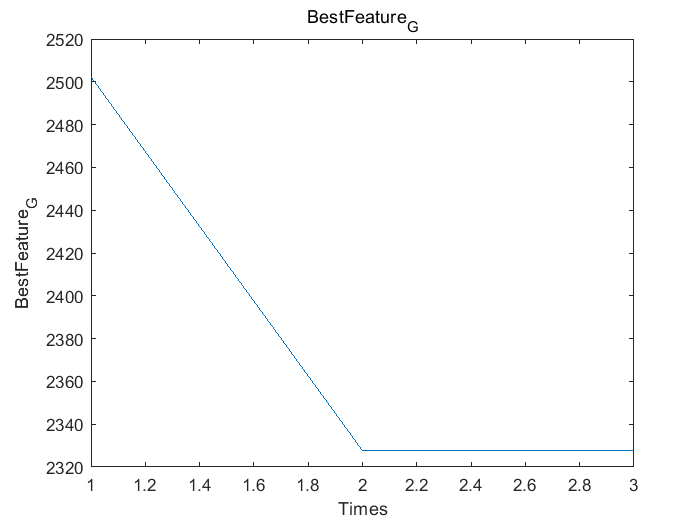

 figure(1); 
 plot(time,BestFeature_G); 
 title('BestFeature_G')
 xlabel('Times');ylabel('BestFeature_G'); 

 save BestS_WillWatson3.mat p;